# Nonlinear building Model under Seismic Excitation

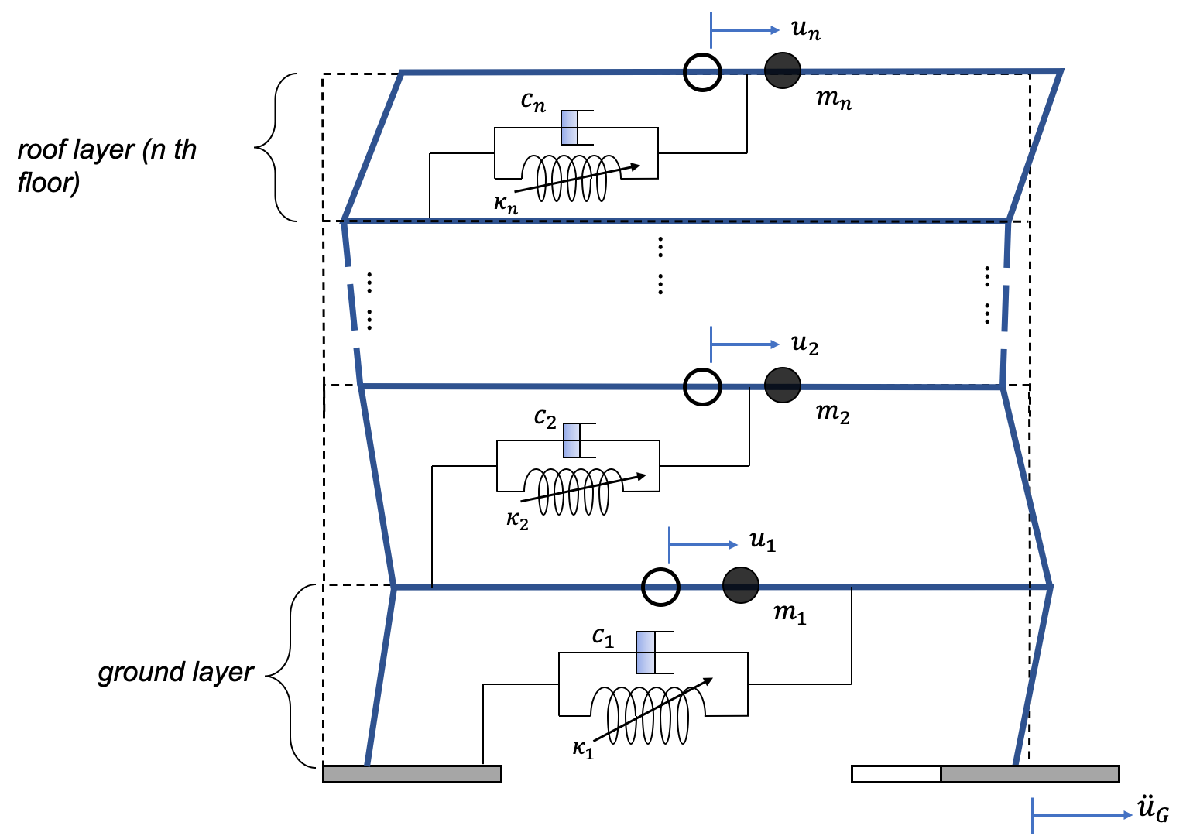

## Generate model

n = 10;
m = 3;
k = 2000;
c = 50;
kappa2 = 0;
kappa3 = 0;

[M,C,K,fnl] = build_model(n,m,c,k,kappa2,kappa3);

## Dynamical system setup 

We consider the stochastic forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}_{nl}(\mathbf{x},\dot{\mathbf{x}})=\mathbf{f}_{stochastic}(\mathbf{x},t)$$


nRealization=1;
T0=100; %% PSD frequency domain resolution is ~ 1/T0
nPoints=2^14; %% control the accuracy of numerical differential equation
epsilon=100; %% forcing magnitude
[filterPSD,forcingdof,stochastic_f] = build_stochasticF(nPoints,epsilon);

We assume stochastic forcing of the form that has a specific PSD. We identify the stochastic forcing by input a white noise to a second order system:

                                            
$$\mathbf{M_i}\ddot{\mathbf{x}}+\mathbf{C_i}\dot{\mathbf{x}}+\mathbf{K_i}\mathbf{x}=\mathbf{W}_{white noise}$$


We take the PSD of the response $<\mathbf x_1,\mathbf x_1>$ over the time domain as the input to the Quarter Car system

setting for the SDE solver and allocate desired output PSD pairs

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

SS = StochasticSystem();
set(SS,'M',M,'C',C,'K',K,'fnl',fnl);
set(SS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

% SDE=StochasticSystem(DS,'System');
set(SS,'filterPSD',filterPSD,'linear',false)
SS.add_random_forcing(nRealization, T0, nPoints,forcingdof);

method="filter ImplicitMidPoint"; %% asigning output and solving method
PSDpair=[n,n];

## Solve full system

[V, D, W] = DS.linear_spectral_analysis();
firts_res=abs(imag(D(1)));
[w,outputPSD] = SDE.sde_solver(method,PSDpair);

## Calculation of linear response

linear_analytic=SDE.compute_linear_PSD(SDE.input.omega,SDE.input.PSD);

## This section plots the result of the full system response and linear analytical

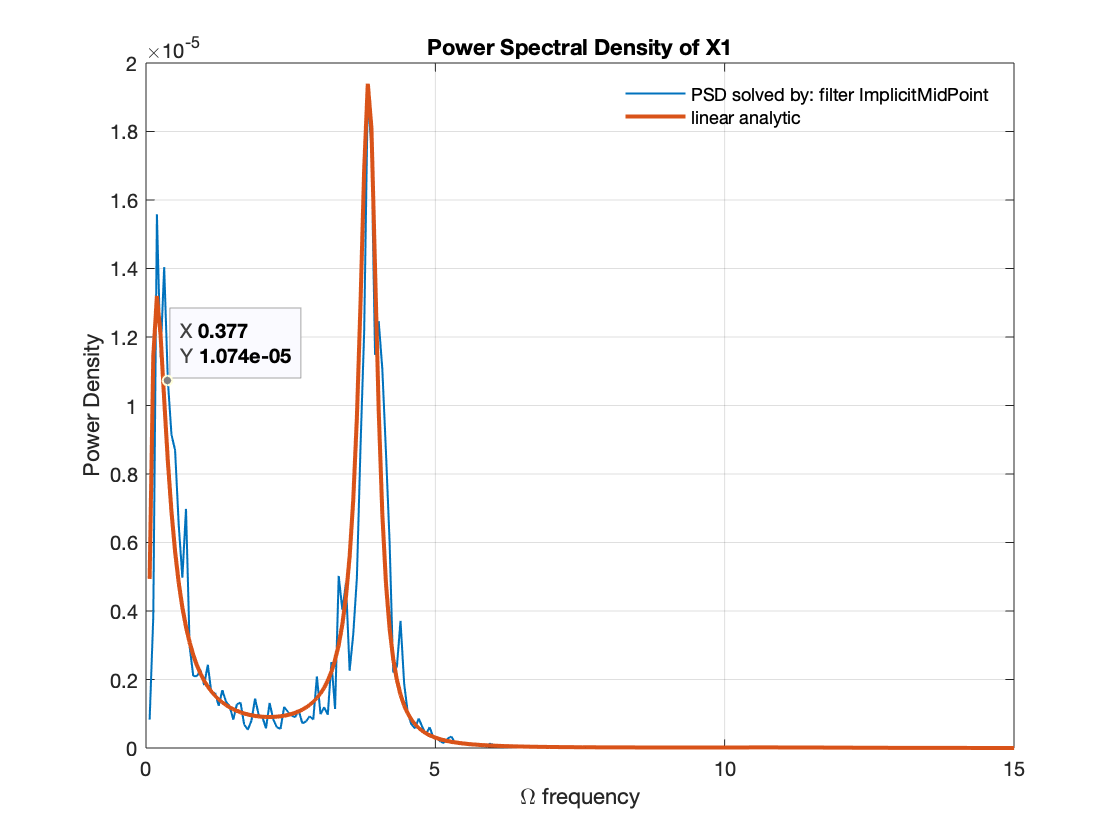

figure
plot(w,outputPSD(1,:),'linewidth',1)
hold on
plot(w,linear_analytic(n,:),'linewidth',2)
xlim([0,15])
xlabel('\Omega frequency')
ylabel('Power Density')
legend(strcat('PSD solved by ', ": ",method), 'linear analytic')
legend('boxoff')
title('Power Spectral Density of X1')
grid on

## SSM setting and compute PSD from SSM

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
masterModes = [1,2];
S.choose_E(masterModes);
order = 5; % SSM approximation order
SDE.SSM=S;
ssmPSD=SDE.extract_PSD([0 20], order,"filter");
%%% stochastic SSM that includes SMM

## Compare the results of SSM, full system response and linear response

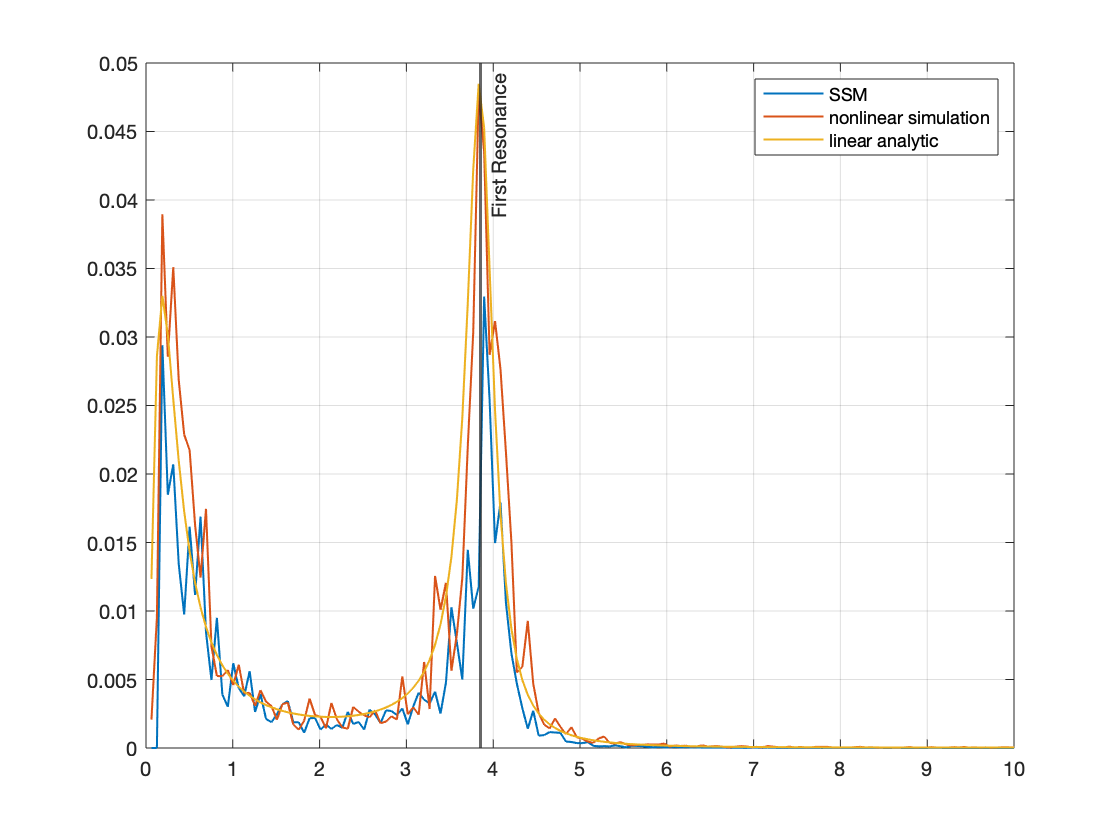

figure
plot(ssmPSD.omega,ssmPSD.PSD,'linewidth',1)
hold on
plot(w,outputPSD(1,:),'linewidth',1)
hold on
plot(w,linear_analytic(n,:),'linewidth',1)
xline(firts_res,'-',{'First Resonance'},'linewidth',1.5);
legend('SSM','nonlinear simulation','linear analytic')
xlim([0,10]);
grid on